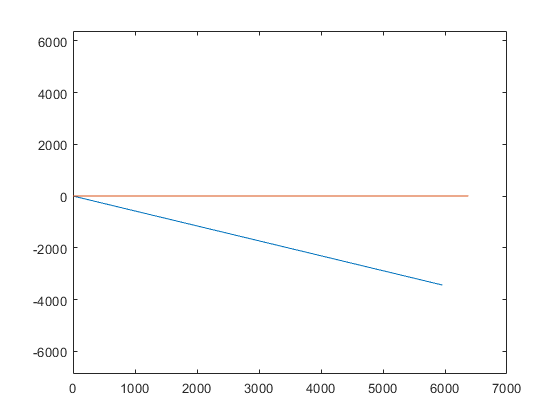

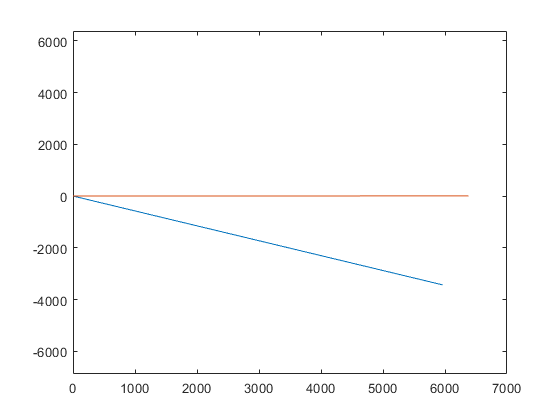

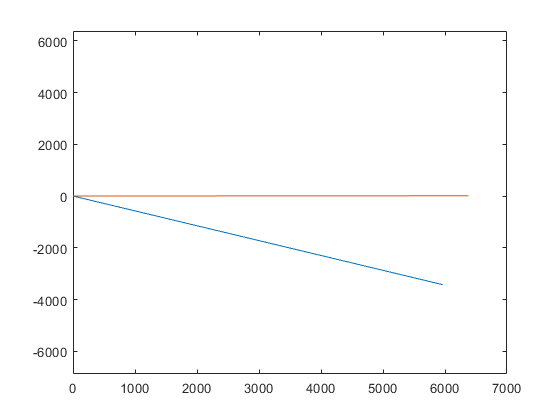

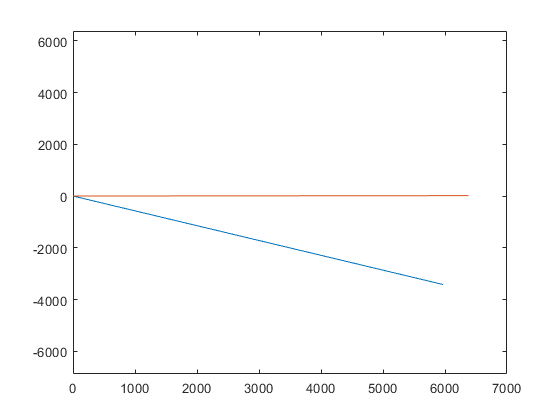

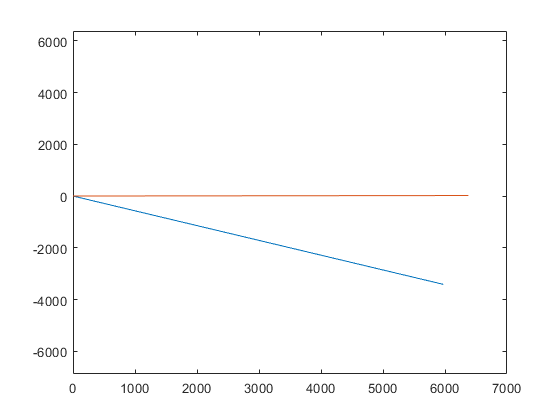

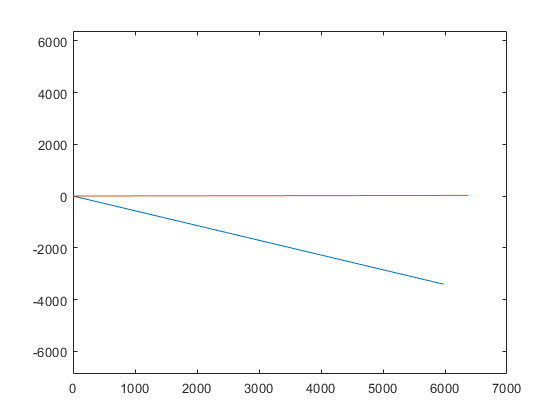

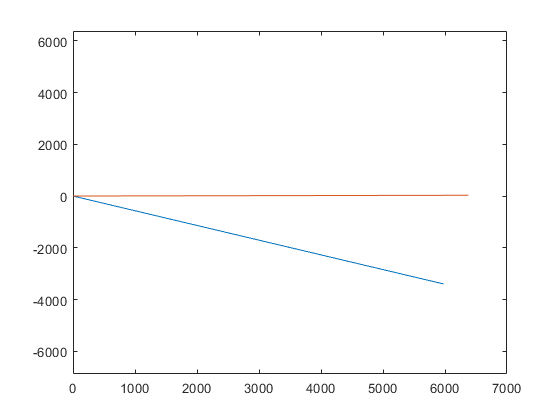

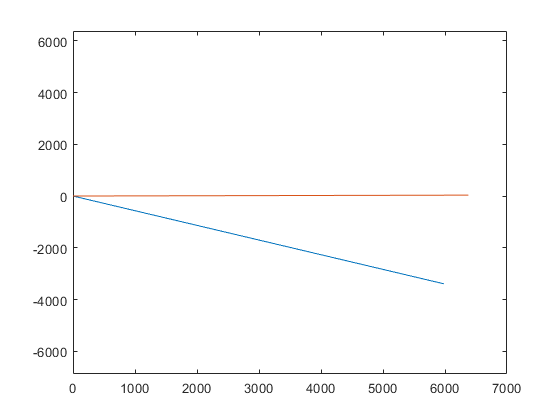

sat = [6878*cos(pi/6); -6878*sin(pi/6)];
ground = [6378; 0];
d_ts = 2*pi/5708;
d_tg = 60*82.5/(6378*(10^3));
A_s = [cos(d_ts), -sin(d_ts); 
        sin(d_ts), cos(d_ts)];
A_g = [cos(d_tg), -sin(d_tg); 
        sin(d_tg), cos(d_tg)];
gif = 'Animated.gif';
for i = 1:300
    h = figure;
    plotv(sat);
    hold on
    plotv(ground)
    hold off
    ylim([-6878, 6378])
    
    sat = A_s * sat;
    ground = A_g * ground;
    
    frame = getframe(h); 
    im = frame2im(frame); 
    [imind,cm] = rgb2ind(im,256);
    
    if i == 1
        imwrite(imind,cm,gif,'gif','DelayTime',0.0001,'Loopcount',inf);  
    else 
        imwrite(imind,cm,gif,'gif','WriteMode','append'); 
    end
    
end